% For reproducibility
rng(2021);
% Loading test data
filename_2 = 'airline_test.csv';
test = readtable(filename_2,'VariableNamingRule','preserve');
test = removevars(test,{'Var1'});
test

test = 25893×23 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness    Departure Delay in Minutes    Arrival Delay in Minutes    satisfaction
    ______    _____________    ___    ______________    __


% Divide dependent variable and independent variable
% Also, as can be seen from correlation matrix, arrivial and departure
% delayed in minutes are removed as this is not interestingly correlated
% with satisfaction
% Dataset used for prediction was choosen for 1250 samples for
% computational reasons
y_test = test(1:1250,23)

y_test = 1250×1 table
    satisfaction
    ____________

         1      
         1      
         0      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         1      
         0      
         1      
         1      
         1      
         0      


X_test = test(1:1250,1:20)

X_test = 1250×20 table
    Gender    Customer Type    Age    Type of Travel    Class    Flight Distance    Inflight wifi service    Departure/Arrival time convenient    Ease of Online booking    Gate location    Food and drink    Online boarding    Seat comfort    Inflight entertainment    On-board service    Leg room service    Baggage handling    Checkin service    Inflight service    Cleanliness
    ______    _____________    ___    ______________    _____    _______________    _____________________    ______________________


% Load the pre-trained model from cross-validation
load('Naive_Bayes_Train_With_HPtuning')

% Predict test dataset
pred_test = predict(Mdl_NB, X_test);
pred_test

pred_test =      1
     1
     0
     0
     0
     0
     1
     1
     1
     1



Confusion_Matrix = confusionmat(y_test.satisfaction,pred_test);
Confusion_Matrix

Confusion_Matrix =    616    64
   106   464




% Visualise heatmap for correaltion matrix
h = heatmap(Confusion_Matrix)

h =   HeatmapChart with properties:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  Show all properties


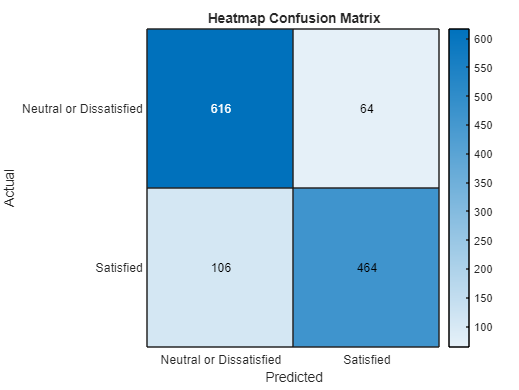

h.Title = 'Heatmap Confusion Matrix';
h.XLabel = 'Predicted';
h.YLabel = 'Actual';
h.XDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};
h.YDisplayLabels = {'Neutral or Dissatisfied','Satisfied'};



% Show the accuracy
Accuracy = trace(Confusion_Matrix)/sum(Confusion_Matrix, 'all')

Accuracy = 0.8640


% Calcurate precision and recall
diagonal = diag(Confusion_Matrix)

diagonal =    616
   464


sum_rows = sum(Confusion_Matrix, 2)

sum_rows =    680
   570



precision = diagonal ./ sum_rows

precision =     0.9059
    0.8140


mean_precision = mean(precision)

mean_precision = 0.8600


sum_columns = sum(Confusion_Matrix, 1)

sum_columns =    722   528



recall = diagonal ./ sum_columns'

recall =     0.8532
    0.8788


mean_recall = mean(recall)

mean_recall = 0.8660


% Calcurate F1 score based upon precision and recall
f1_score = 2*((mean_precision*mean_recall)/(mean_precision+mean_recall))

f1_score = 0.8630